clear
filename = 'example_data_steady_states.txt';
data=[];

fileID = fopen(filename,'r');
formatSpec = '%f';
size_data=[4 inf];
data=[data fscanf(fileID,formatSpec,size_data)];
fclose(fileID);

t_sims=data(1, :);
v_sims=data(2, :);
b_sims=data(3, :);
i_sims=data(4, :);

Tmax=1000;
B0=1000;
alpha=3*10^-6;
beta=100;
tau=15;
delta=0.1;

B=zeros(1, Tmax);
I=zeros(1, Tmax);
V=zeros(1, Tmax);

B(1)=B0;
V(1)=2*B0;

t=1;
while t<Tmax
    t=t+1;
    if t<tau+2
        B(t)=B(t-1)-alpha*V(t-1)*B(t-1);
        I(t)=I(t-1)+alpha*V(t-1)*B(t-1);
        V(t)=V(t-1)-alpha*V(t-1)*(B(t-1)+I(t-1))-delta*V(t-1);
    else
        B(t)=B(t-1)-alpha*V(t-1)*B(t-1)+alpha*V(t-1-tau)*B(t-1-tau);
        I(t)=I(t-1)+alpha*V(t-1)*B(t-1)-alpha*V(t-1-tau)*B(t-1-tau);
        V(t)=V(t-1)-alpha*V(t-1)*(B(t-1)+I(t-1))-delta*V(t-1)+alpha*beta*V(t-1-tau)*B(t-1-tau);
    end
end

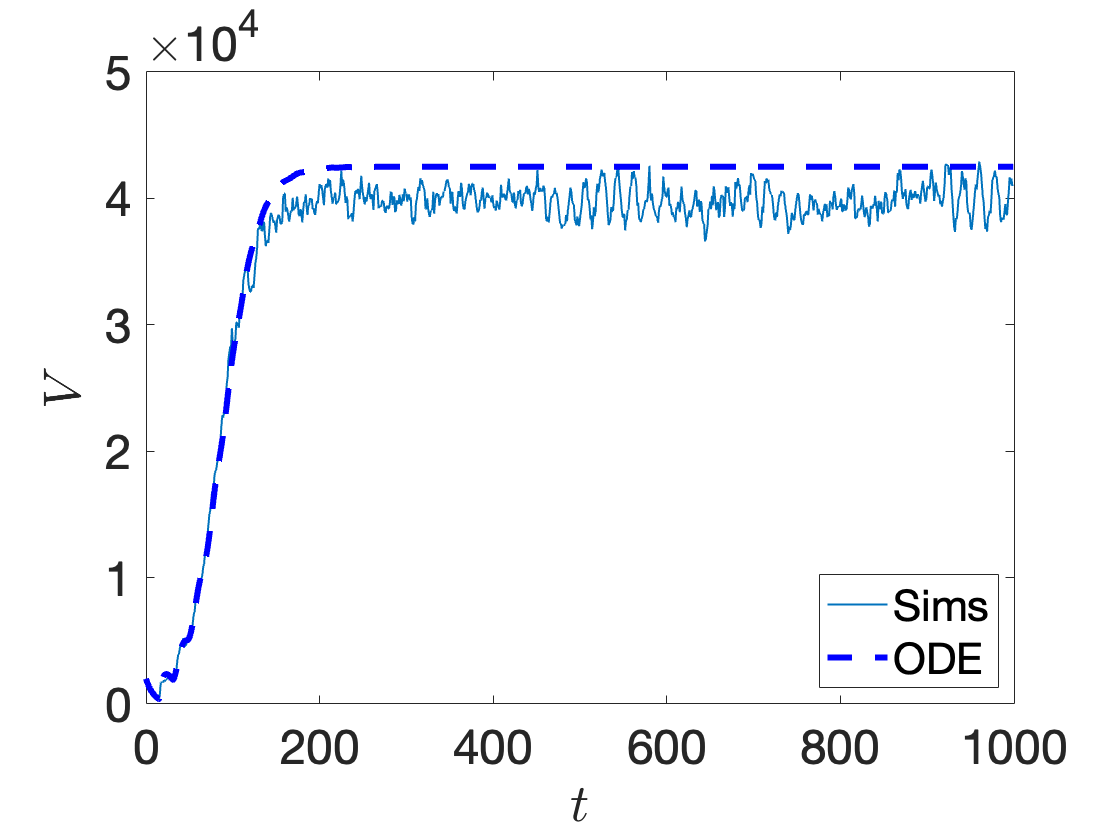

plot(t_sims,v_sims, 'LineWidth', 1)
hold on
plot(t_sims,V, 'b--', 'LineWidth', 3)
hold off
xlabel('$t$', 'Interpreter',"latex")
ylabel('$V$', 'Interpreter',"latex")
legend('Sims', 'ODE', 'Location','southeast')
set(gca, 'fontsize', 24)

V_ss=mean(V(500:end))

V_ss = 4.2503e+04

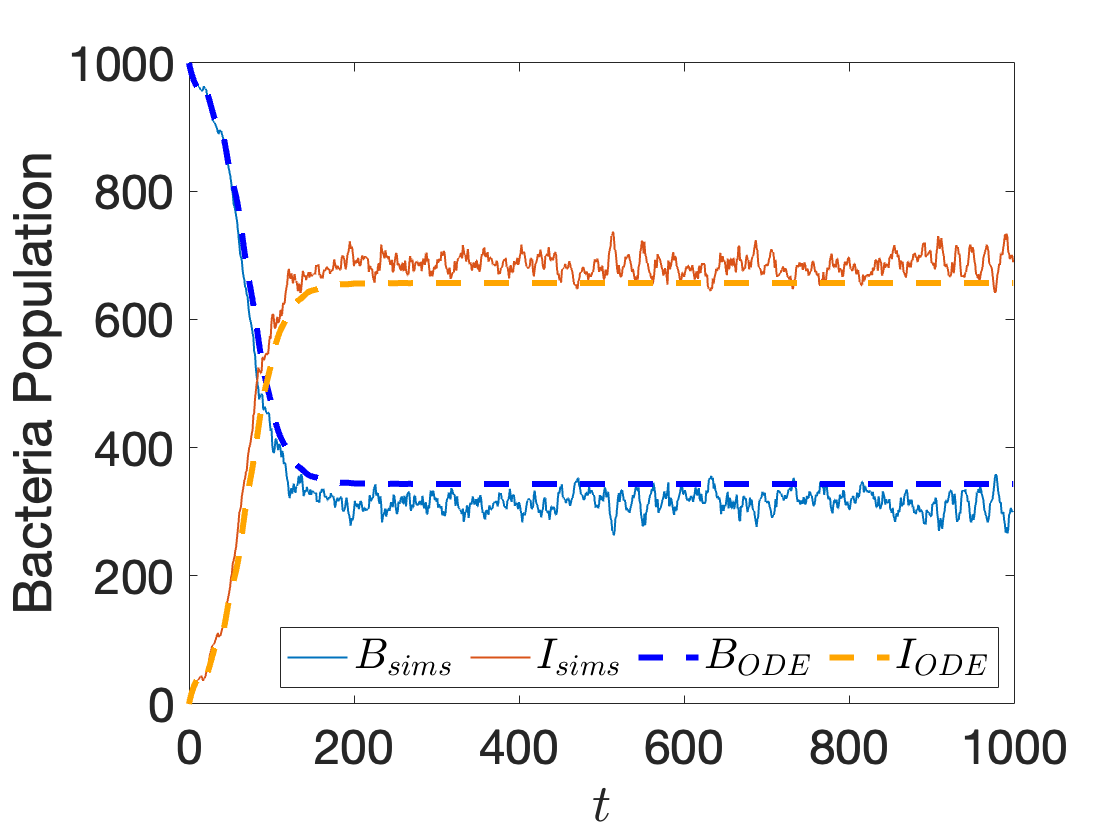

plot(t_sims,b_sims, 'LineWidth', 1)
hold on
plot(t_sims,i_sims, 'LineWidth', 1)
plot(t_sims, B, 'b--', 'LineWidth', 3)
plot(t_sims, I, '--', 'LineWidth', 3, 'Color',[1 165/255 0])
hold off
xlabel('$t$', 'Interpreter',"latex")
ylabel('Bacteria Population')
legend('$B_{sims}$', '$I_{sims}$', '$B_{ODE}$', '$I_{ODE}$', 'Interpreter', 'latex', 'Location','southeast', 'Orientation',"horizontal")
set(gca, 'fontsize', 24)

B_ss=mean(B(500:end))

B_ss = 343.3333

I_ss=mean(I(500:end))

I_ss = 656.6667

% alpha2=3*10^-6;
% beta2=100;
% tau2=15;
% I2=zeros(1, Tmax);
% V2=zeros(1, Tmax);
% B(1)=B0;
% V(1)=2*B0;

% t=1;
% while t<Tmax
%     t=t+1;
%     if t<tau+2
%         B(t)=B(t-1)-alpha*V(t-1)*B(t-1);
%         I(t)=I(t-1)+alpha*V(t-1)*B(t-1);
%         V(t)=V(t-1)-alpha*V(t-1)*(B(t-1)+I(t-1))-delta*V(t-1);
%     elseif t<300
%         B(t)=B(t-1)-alpha*V(t-1)*B(t-1)+alpha*V(t-1-tau)*B(t-1-tau);
%         I(t)=I(t-1)+alpha*V(t-1)*B(t-1)-alpha*V(t-1-tau)*B(t-1-tau);
%         V(t)=V(t-1)-alpha*V(t-1)*(B(t-1)+I(t-1))-delta*V(t-1)+alpha*beta*V(t-1-tau)*B(t-1-tau);
%     else
%         if t==300
%             V2=V/2;
%             V=V/2;
%             I2=I/2;
%             I=I/2;
%         end
%         B(t)=B(t-1)-alpha*V(t-1)*B(t-1)+alpha*V(t-1-tau)*B(t-1-tau)-alpha2*V2(t-1)*B(t-1)+alpha2*V2(t-1-tau2)*B(t-1-tau2);
%         I(t)=I(t-1)+alpha*V(t-1)*B(t-1)-alpha*V(t-1-tau)*B(t-1-tau);
%         V(t)=V(t-1)-alpha*V(t-1)*(B(t-1)+I(t-1))-delta*V(t-1)+alpha*beta*V(t-1-tau)*B(t-1-tau);
%         I2(t)=I2(t-1)+alpha2*V2(t-1)*B(t-1)-alpha2*V2(t-1-tau2)*B(t-1-tau2);
%         V2(t)=V2(t-1)-alpha2*V2(t-1)*(B(t-1)+I2(t-1))-delta*V2(t-1)+alpha2*beta2*V2(t-1-tau2)*B(t-1-tau2);
%     end
% end
% V2(1:300)=0;
% V(1:300)=V(1:300)*2;

% plot(V, 'LineWidth', 3)
% hold on
% plot(V2, 'LineWidth', 3)
% hold off
% xlabel('time', 'Interpreter',"latex")
% ylabel('phage', 'Interpreter',"latex")
% title('Neutral', 'Interpreter',"latex")
% set(gca, 'fontsize', 24)